# Domaći zadatak iz predmeta Obrada i prepoznavanje govora

# Danica Bandović 2018/0018 

## Prvi zadatak

#### 1.Korišćenjem komercijalnog mikrofona u programskom okruženju MATLAB, snimiti govornu sekvencu u dužini od 20-ak sekundi. Sekvencu snimiti sa frekvencijom odabiranja 8 ili 10 kHz, u kojoj se nalazi desetak jasno segmentiranih reči.

Kod pomoću kog je snimljena tražena sekvenca nalazi se u ćelijama ispod. Snimljena sekvenca sačuvana je i nalazi se u okviru fajla sekvenca.wav. Za frekvenciju odabiranja odabrano je 8 kHz, snimljano je 20 sekundi i izgovoreno je 10 reči.

% inicijalizacija parametara za snimanje sekvence
clear
close all
clc
fs = 8000;
T = 1/fs;
trajanje = 20; %8 sekundi za prvi pod 3
N = trajanje*fs;
nbits = 16;
nchans = 1;

% snimanje sekvence

%x = audiorecorder(fs,nbits,nchans);
%disp('Start.')

Start.


%recordblocking(x, trajanje);
%disp('Stop.')

Stop.


%pustanje snimljene sekvence

%play(x)
%y = getaudiodata(x);
%sound(y, fs); %podraz. fs = 8192
%potrebno je da vrednosti y budu u intervalu (-1,1)


%audiowrite('sekvenca.wav', y, fs);


#### 2. Korišćenjem kratkovremenske energije i kratkovremenske brzine prolaska kroz nulu izvršiti određivanje početka i kraja pojedinih reči. Dobijeni rezultat prikazati grafički. Preslušati segmentirane delove zvučne sekvence i komentarisati dobijeni rezultat. (Po želji se ovaj postupak može ponoviti primenom Teager energije).

### ***TEORIJSKI OSVRT:***

Pošto se značajne promene u govornom signalu ne dešavaju tako brzo često se u obradi govora u vremenskom domenu koriste kratkovremenske karakteristike signala. One podrazumevaju da se obrada signala vrši na odbircima koji su smešteni u okviru jednog kratkog vremenskog intervala. Ukupna energija signala ne nosi informaciju o pojavi zvučniih i bezvučnih delova signala ($E = \sum_{m=-\infty}^{\infty} x^{2}(m)$). Za razliku od nje, kratkovremenska energija se definiše kao 


$$E_{n} = \sum_{m=n-N+1}^{n}x^{2}(m)$$


gde se energija ra;una kao zbir kvadrata N poslednjih odbiraka iz intervala (n-N+1) do n. Izraz se može napisati i kao 


$$E_{n} = \sum_{m=-\infty}^{\infty}[x(m)w(n-m)]^{2}$$


gde je w(n) neka prozorska funkcija. Prethodni izraz može se zapisati i na sledeći način:


$$E_{n} = \sum_{m=-\infty}^{\infty}x^{2}(m)h(n-m), h(n) = w^{2}(n)$$


Ideja je da se kratkovremenska energija može dobiti kao izlaz iz filtra čiji je ulaz $x^{2}(n)$ a impulsni odyiv filtra h(n), i to niskofrekvencijskog jer je pretpostavka da se E ne menja brzo. Najčešći oblici prozoskih funkcija koji se koriste su pravougaona i Hamingova prozorska funkcija. Dužina prozorske funkcije iznosi 1 do 3 pitch periode.

O sadržaju snimljene sekvence može nam dosta toga reći i kratkovremenska brzina prolaska kroz nulu. To je mera frekventnog sadržaja signala. Ako u signalu ima dosta visokih učestanosti ova veličina će biti velika. Brzina prolaska kroz nulu je $Z=\frac{N_{0}}{N}$, gde je N broj posmatranih odbiraka a $N_{0}$ broj odbiraka koji nisu istog znaka kao njihovi prethodnici. Pošto govorni signal sadrži frekvemcijske komponente iz širokog spektra učestanosti, Z nije baš precizno, i zato koristimo kratkovremenski oblik :


$$Z_{n} = \sum_{m=-\infty}^{\infty}[sgn[x(m)]-sgn[x(m-1)]]x(n-m)$$



$$w(n) = \frac{1}{2N}, 0\leq n \leq N-1, inace \quad w(n)=0
        $$


Z će biti manje za govorni signal nego za bezvučni govor i šum.

Pri segmentaciji govornog dela signala, nakon računanja kratkovremenske energije i kratkovremenske brzine prolaska kroz nulu, potrebno je na osnovu energije naći dovoljno veliki prag ITU koji nam služi da ako je energija veća od ovog praga sigurno znamo da u tom intervalu imamo govorni signal. Drugi korak je određivanje praga ITL, koji služi kao donji prag, da bismo odredili početak i kraj govornog dela signala. Od onog trenutka kada je energija veća od ITU, idemo levo i desno u vremenu sve dok ne pronađemo trenutke kada je energija manja od donjeg praga, i to su potencijalni početak i kraj reči. Potom se posmatra brzina prolaska kroz nulu 25 prozorskih funkcija levo od početka i desno od kraja reči. Ako je Z 3 ili više puta presekla određeni prag, uzima se nova tačka za početak, odnosno kraj reči.

### ***REZULTATI:***

Prvo što ćemo uraditi jeste da grafički prikažemo snimljenu sekvencu, odnosno prikazaćemo odbirke snimljenog zvučnog signala u vremenu.

%prikaz snimljene sekvence u vremenskom domenu
[y,fs] = audioread('sekvenca.wav');

figure
plot(0:1/fs:(length(y)-1)/fs, y);
title('Govorna sekvenca'); xlabel('t[s]'); ylabel('y(t)');

figure
plot(abs(fftshift(fft(y))))


Na grafiku se primećuje 10 izdvojenih segmenata. Na početku sekvence se primećuje određeni šum koji je ili posledica mikrofona ili nekih spoljašnjih zvukova, i s obzirom da u prve dve, tri sekunde nije izgovorena nijedna reč, možemo čak i posmatrati deo sekvence tek od treće sekunde. Ono što će biti pokušano u daljem radu jeste da se pomoću kratkovremenske energije i kratkovremenskog ZCR-a izdvoje svih pojedinačnih 10 izgovorenih reči.

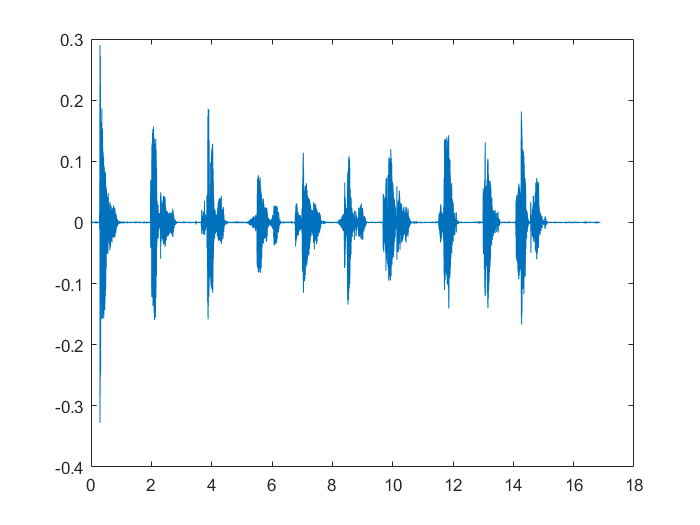

%POGLEDATI DA LI JE POTREBAN NF FILTAR, ALI GENERALNO NA GRAFIKU JAKO LEPO
%DELUJE DA JE ŠUM POTISNUT, SA GRAFIKA FFT-a SE NE VIDI DA POSTOJI
%DC KOMPONENTA TE NE DELUJE DA JE BILO ŠTA POTREBNO DA SE FILTRIRA
%y = y(25000:end);
%figure
%plot(0:1/fs:(length(y)-1)/fs, y);

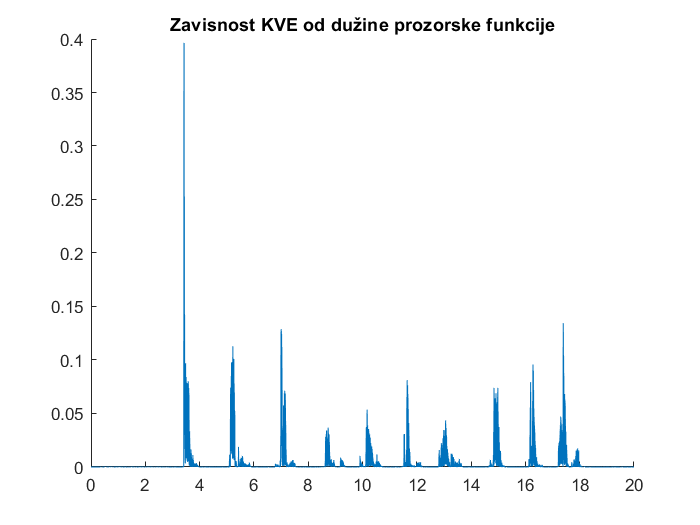

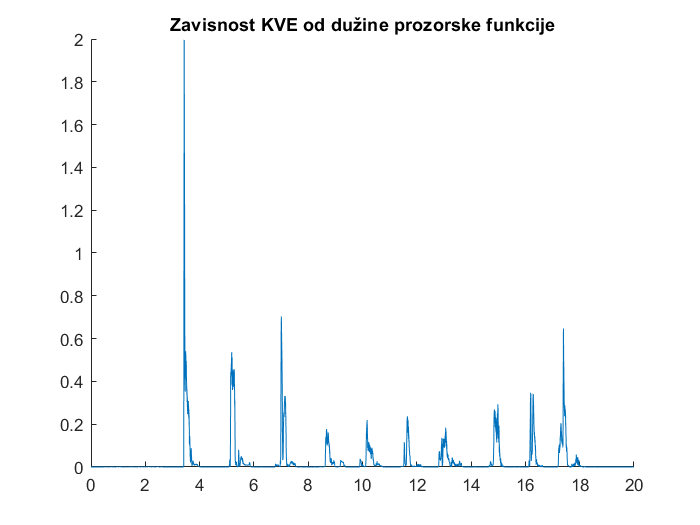

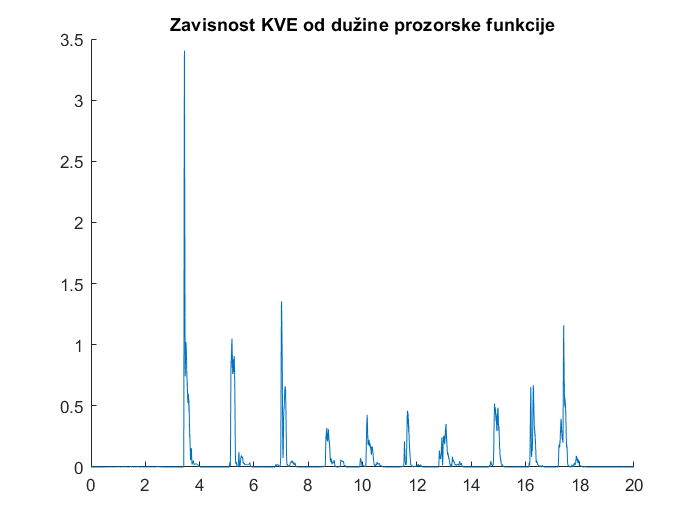

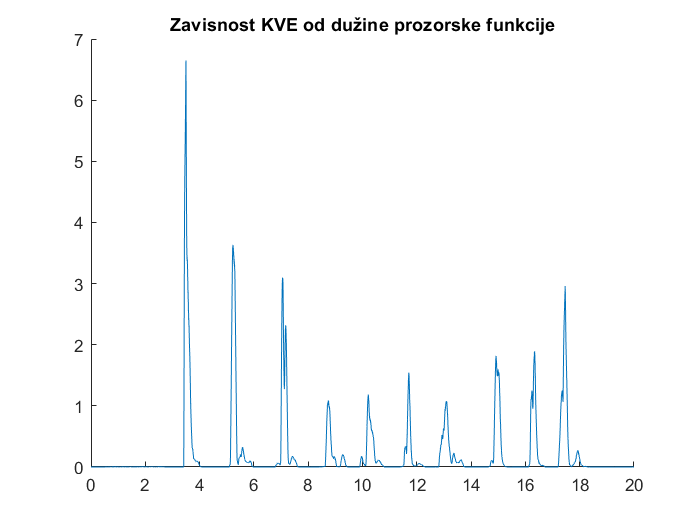

%uticaj velicine prozora, kratkovremenska energija, pravougaoni prozor
T = 1/fs;
for wl = fs*[1e-3 10e-3 20e-3 80e-3]
    E = zeros(size(y));
    for i = wl:length(y)
        rng = (i-wl+1) : i;
        E(i) = sum(y(rng).^2);
    end
    figure();
    hold on;
    time = T:T:length(E)*T;
    plot(time, E);
    title('Zavisnost KVE od dužine prozorske funkcije')
    hold off;
    
end

## uticaj prozorske funkcije

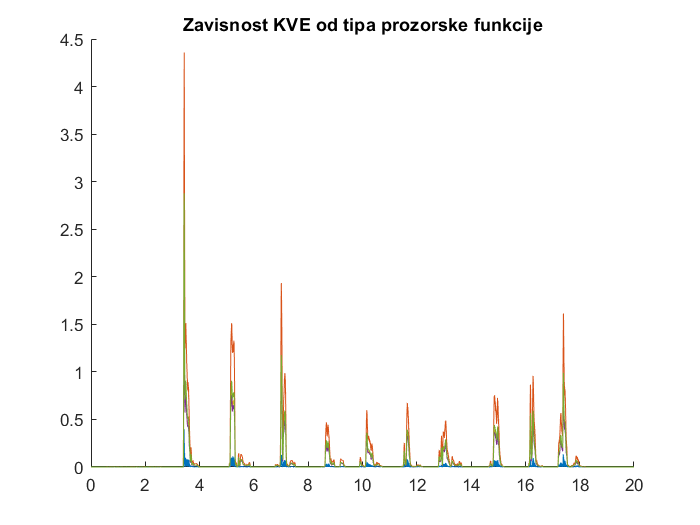

wl = fs*30e-3+1; % da bi se omogucilo da prozorske funkcije budu simetricne

for p = 1:4
    switch p
        case 1
            win = rectwin(wl); %pravougaoni prozor
        case 2
            win = hamming(wl); %Hamingov prozor
        case 3
            win = hann(wl); %Hanov prozor
        case 4
            win = kaiser(wl, 4); % Kajzerov prozor, beta = 4
    end
    
    E = zeros(size(y)); % energija
    for i = (wl+1)/2: length(y)-wl/2
        rng = (i-(wl-1)/2) : (i+(wl-1)/2); % centrirano oko trenutnog odbirka
        E(i) = sum(y(rng).^2.*win); % suma kvadrata wl odbiraka
    end
    
    figure(4);
    title('Zavisnost KVE od tipa prozorske funkcije')
    hold on;
    time = T:T:length(E)*T;
    plot(time, E);
    hold off;
    
end

%pret_y = y;
%y = pret_y(136000:end);
%time1 = time;
%time = time1(136000:end);

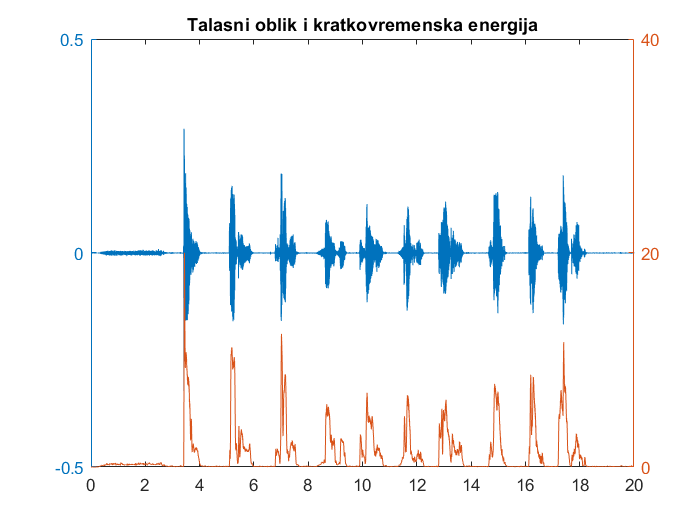

%prozor od 20ms, pravougaona prozorska fja

%pojedine reci
%y = y(136000:end);

wl = fs*20e-3;
E = zeros(size(y));
Z = zeros(size(y));
M = zeros(size(y));
for i= wl : length(y)
    rng = (i-wl+1):i-1;
    E(i) = sum(y(rng).^2);
    M(i) = sum(abs(y(rng)));
    Z(i) = sum(abs(sign(y(rng+1)) - sign(y(rng))));
end
Z = (Z/2)/wl;

figure
plotyy(time, y, time, M);
title('Talasni oblik i kratkovremenska energija');

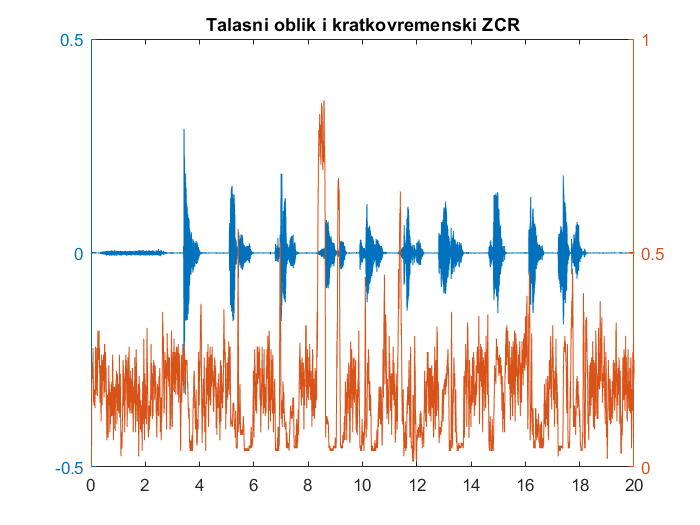

figure
plotyy(time, y, time, Z);
title('Talasni oblik i kratkovremenski ZCR');

Ono što se primećuje sa grafika energije jeste da je prisutan jedan pik čija je vrednost dosta veća u odnosu na ostatak izgovorenih reči. Zbog tog pika ćemo posebno obratiti pažnju na to koju vrednost uzimamo kao gornji prag pri segmentaciji da se ne desi da druge reči čija je energija manja, ne budu prepoznate kao reč. Reči koje imaju dosta samoglasnika i koje su zvučne se veoma lako segmentiraju, poput Ana, dva, tri, dok reči kao što su podrum, drvo, Matlab, nisu bile izdvojene odmah, ili se izdvoji samo jedan deo reči. Na primer, u reči Matlab, mat se izdvoji kao reč jer je drugi deo reči manje naglašen, i sama reč sadrži bezvučne foneme poput t i b. I gornja i donja granica dosta su niske jer je jačina izgovorenih reči različita. Čak i pored toga, reči koje su teže za segmentaciju se ni pored dosta smanjenih pragova ne izdvajaju dobro, već se dešava da se umesto jedne reči izdvoje slogovi kao reci, te se umesto sunce, dobiju dva sloga kao dve reči, sun i ce, a isto se dešava i kod reči matlab. 

S obzirom da postoji veliki pik u energiji, probaćemo koristiti magnitudu umesto energije da bismo uradili segmentaciju. U suprotnom, da bi sve reči bile uočene, potrebno je da su pragovi veoma mali, a čak i tada reč Matlab se nije izdvojila kao jedna, već kao dve reči. Prednost korišćenja kratkovremenske energije u odnosu na kratkovremensku magnitudu je u tome što se jasno izdvaja tišina od reči, ali se problem javlja kod reči koje imaju bezvučne plozive u sebi, nazale ili se završavaju slabim frikativima. Sa druge strane, ako se koristi magnituda uočeno je da je moguće postaviti veće pragove kod segmentacije iz razloga što su vrednosti na svim rečima bliže jedne drugima i nema tolio velikog pika koji se izdvaja, ali je problem korišćenja ovog parametra u tome što u tom slučaju ne može da napravi toliko preciznu granicu između tišine i izgovorene reči, za razliku od kratkovremenske energije.

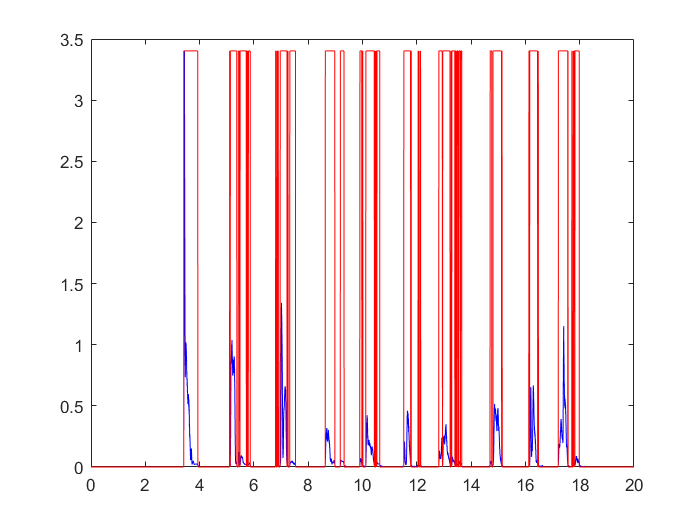

%koriscenje kratkovremenske energije, segmentacija

%prosirenje

ITU = 0.005*max(E); %0.005E
ITL = 0.0001*max(E); %0.0001E

%IMX = max(E);
%IMN = max(E(2500:end));
%I1 = 0.03*(IMX-IMN) + IMN;
%I2 = 4*IMN;
%ITL = min(I1,I2)
%ITU = 5*ITL

pocetak_reci = [];
krajevi = [];

for i=2:length(E)
    if (E(i-1)<ITU)&&(E(i)>=ITU)
        pocetak_reci = [pocetak_reci i];
    end
    if (E(i-1)>ITU)&&(E(i)<=ITU)
        krajevi = [krajevi i];
    end
end

rec = zeros(length(E),1);
for i=1:length(pocetak_reci)
    rec(pocetak_reci(i):krajevi(i)) = max(E)*ones(krajevi(i)-pocetak_reci(i)+1,1);
end

figure
plot(time,E,'b', time, rec, 'r');

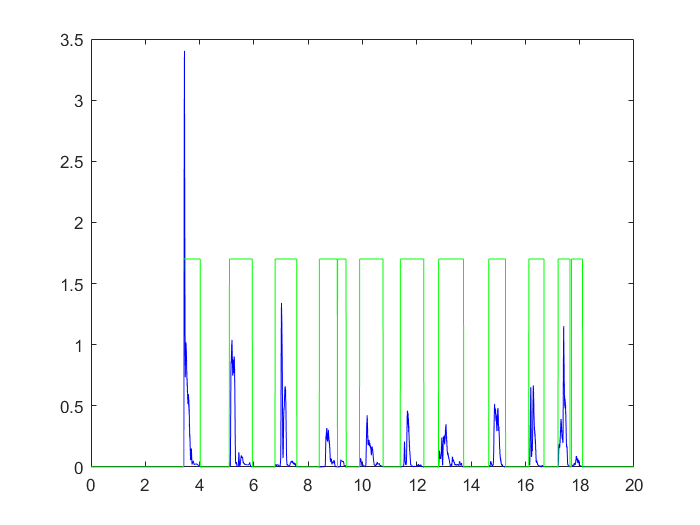

for i=1:length(pocetak_reci)
    pomeranje = pocetak_reci(i);
    while (E(pomeranje)>ITL)
        pomeranje = pomeranje-1;
    end
    pocetak_reci(i) = pomeranje;
end

for i=1:length(krajevi)
    pomeranje = krajevi(i);
    while(E(pomeranje)>ITL)
        pomeranje = pomeranje + 1;
    end
    krajevi(i) = pomeranje;
end

poc1(1) = pocetak_reci(1);
k = 1;
for i=2:length(pocetak_reci)
    if pocetak_reci(i)~=poc1(k)
        k=k+1;
        poc1(k) = pocetak_reci(i);
    end
end

kraj1(1) = krajevi(1);
k = 1;
for i=2:length(krajevi)
    if krajevi(i)~=kraj1(k)
        k=k+1;
        kraj1(k) = krajevi(i);
    end
end

pocetak = poc1;
kraj = kraj1;

rec = zeros(length(y),1);
for i=1:length(pocetak)
    rec(pocetak(i):kraj(i),1) = max(E)*ones(kraj(i)-pocetak(i)+1,1);
end

figure
plot(time, E, 'b', time, rec/2, 'g');
hold off

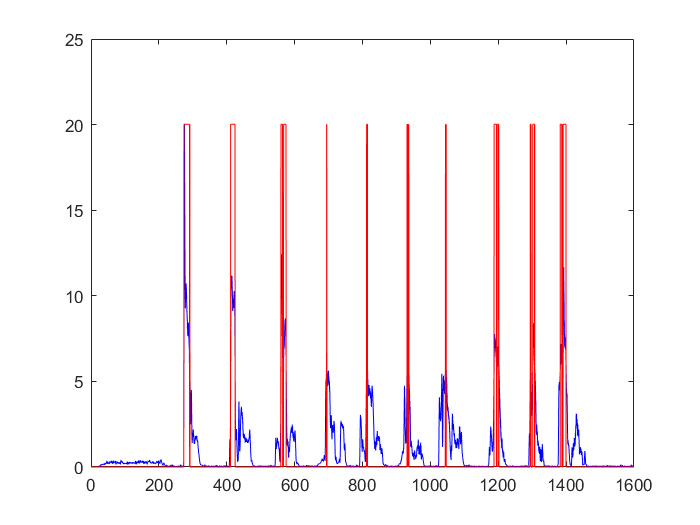

%segmentacija koriscenjem magnitude

ITU = 0.29*max(M); %0.005E
ITL = 0.002*max(M); %0.0001E

%IMX = max(E);
%IMN = max(E(2500:end));
%I1 = 0.03*(IMX-IMN) + IMN;
%I2 = 4*IMN;
%ITL = min(I1,I2)
%ITU = 5*ITL

pocetak_reci = [];
krajevi = [];

for i=2:length(M)
    if (M(i-1)<ITU)&&(M(i)>=ITU)
        pocetak_reci = [pocetak_reci i];
    end
    if (M(i-1)>ITU)&&(M(i)<=ITU)
        krajevi = [krajevi i];
    end
end

rec = zeros(length(M),1);
for i=1:length(pocetak_reci)
    rec(pocetak_reci(i):krajevi(i)) = max(M)*ones(krajevi(i)-pocetak_reci(i)+1,1);
end

figure
plot(time,M,'b', time, rec, 'r');

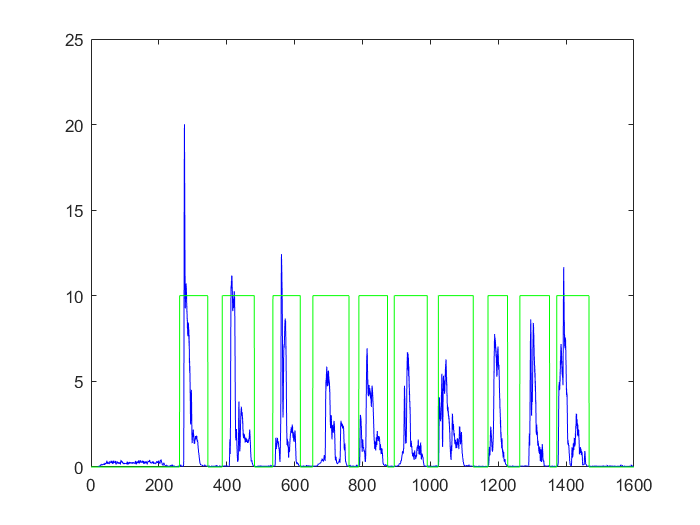


%prosirenje

for i=1:length(pocetak_reci)
    pomeranje = pocetak_reci(i);
    while (M(pomeranje)>ITL)
        pomeranje = pomeranje-1;
    end
    pocetak_reci(i) = pomeranje;
end

for i=1:length(krajevi)
    pomeranje = krajevi(i);
    while(M(pomeranje)>ITL)
        pomeranje = pomeranje + 1;
    end
    krajevi(i) = pomeranje;
end

poc1(1) = pocetak_reci(1);
k = 1;
for i=2:length(pocetak_reci)
    if pocetak_reci(i)~=poc1(k)
        k=k+1;
        poc1(k) = pocetak_reci(i);
    end
end

kraj1(1) = krajevi(1);
k = 1;
for i=2:length(krajevi)
    if krajevi(i)~=kraj1(k)
        k=k+1;
        kraj1(k) = krajevi(i);
    end
end

pocetak = poc1;
kraj = kraj1;

rec = zeros(length(y),1);
for i=1:length(pocetak)
    rec(pocetak(i):kraj(i),1) = max(M)*ones(kraj(i)-pocetak(i)+1,1);
end

figure
plot(time, M, 'b', time, rec/2, 'g');
hold off

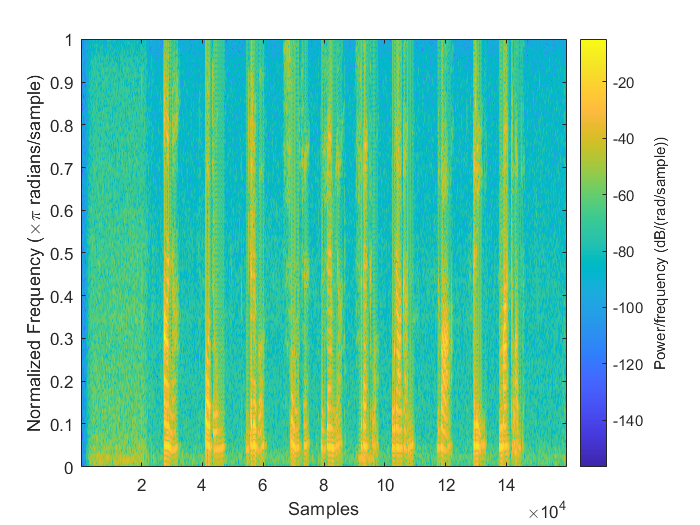

% Teager energija

time = T:T:length(E)*T;
win = ones(1, fs*20e-3); % pravougaoni prozor
noverlap = (fs*20e-3)-fs*10e-3;
figure
spectrogram(y, win, noverlap, 1024, 'yaxis');

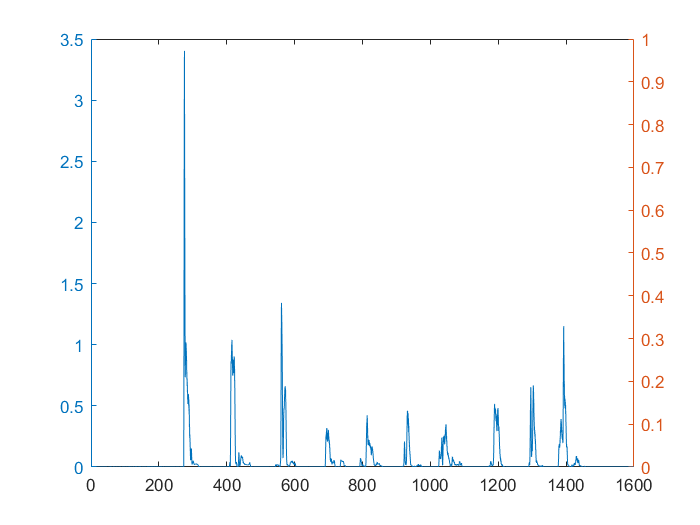


[S, F, T, P] = spectrogram(y, win, noverlap, 128*2, fs, 'yaxis');

Te = zeros(size(T));
for t = 1:length(T)
    Te(t) = sum(abs(P(:,t))); % F ako dajemo na znacaju ucestanosti
end

figure
yyaxis left
plot(time, E);
yyaxis right

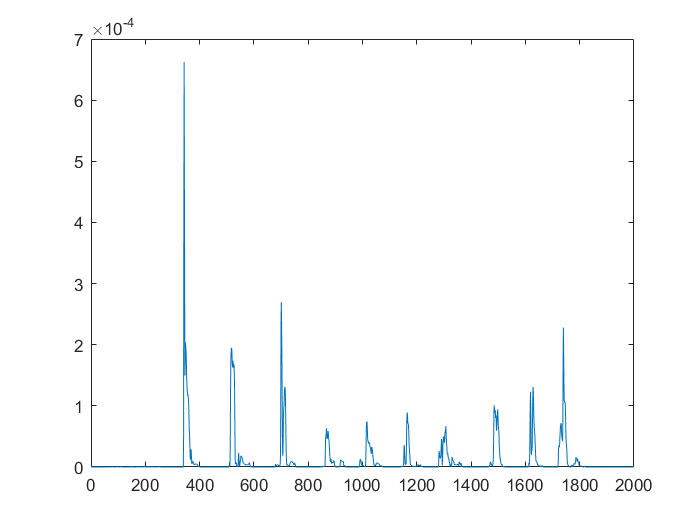

figure
t11= 1:length(Te);
plot(1:length(Te), Te);

%figure
%    histogram(Z(152000:156000),20);
%    pause
%    hold all
%    histogram(Z(70400:74400),20);
%    hold off

%IDEJA DA USREDNJIMO HISTOGRAME ZA SVE RECI
Z1 = [];
figure

for i=1:length(pocetak)
    x = Z(pocetak(i):kraj(i));
    histogram(x,20);
    hold all
    pause
end

Unrecognized function or variable 'pocetak'.

histogram(Z(152000:156000),20);
hold off




Zaključak sa dobijenih histograma je da zbog određenih reči koje su teške za segmentaciju čak ni histogram ne može da bude od velike pomoći s obzirom da se delovi histograma reči koje ima bezvučne plozive u sebi (na primer) dosta preklapaju sa histogramom dela signala koji predstavlja tišinu. Zbog toga i jeste teško naći donju granicu za prag između tiišine i govora.

%slusanje dobijenih reci

for i=1:10
    sound(y(pocetak(i):kraj(i)), fs);
    pause
end

y(N+1:2*N) = 0;
y1 = 8*y;
y2 = 0.2*y;
y3 = -5*y;
y4 = -0.2*y;

sound(y1,fs);
pause(6);
sound(y2,fs);
pause(12);

sound(y3,fs);
pause(20);
sound(y4,fs);

y5 = y(end:-1:1);
sound(y5,fs);

factor=3;
ysporo = zeros(1,factor*length(y));

for k = factor:factor:length(ysporo)
    ysporo(k:k+factor-1) = y(k/factor);
end

sound(ysporo)

ybrzo = zeros(1,floor(length(y)/factor))

for k=1:length(ybrzo)
    ybrzo(k) = y(k*factor)
end
sound(ybrzo)

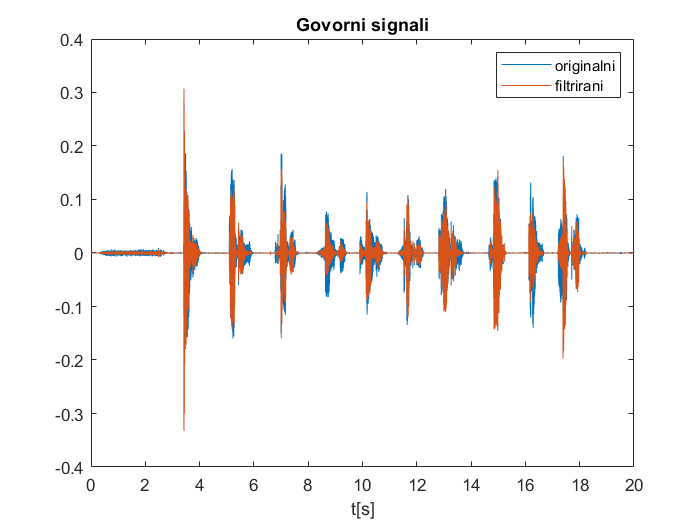

nord = 6;
Wn = [300 3400]/(fs/2);
[b,a] = butter(nord, Wn, 'bandpass');
yf = filter(b,a,y);

figure()
plot(0:1/fs:(length(y)-1)/fs,y);
hold on;
plot(0:1/fs:(length(y)-1)/fs, yf);
title('Govorni signali'); xlabel('t[s]'); legend('originalni', 'filtrirani');


sound(yf,fs);


#### 3.Snimiti novu sekvencu od par reči (bogatih samoglasnicima, recimo onomatopeja,...) i na osnovu tako snimljene sekvence proceniti pitch periodu sopstvenog glasa. Koristiti dve različite metode pa uporediti i komentarisati dobijene rezultate.

### ***TEORIJSKI OSVRT****:*

Pitch-perioda (osnovna učestanost glotisa) je jedan od parametara koji služe da se prepozna govornik, pošto svaka osoba ima sopstvenu pitch-periodu. Postoji više načina za procenu pitch-periode, i u ovom zadatku ćemo se osvrnuti na dva. 

#### ***PRVI METOD:***

Prvi korišćeni metod predložili su Gold i Rabiner, i prikazana je šema algoritma na slici ispod:

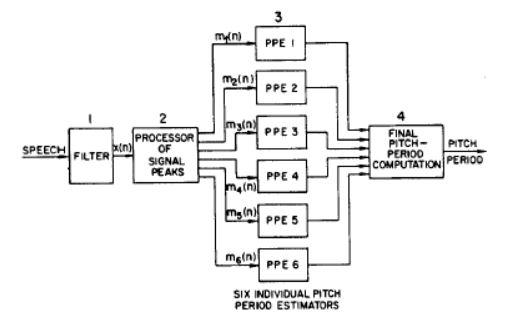

Prvi korak u algoritmu jeste filtriranje ulaznog govornog signala. Pitch-perioda se obično nalazi između 100 i 300 Hz i s obzirom na to se ulazni signal obično propušta kroz filtar propusnik opsega. Na ulaz u procesor pikova dovodi se filtrirani signal, a na izlazu se generiše šest različitih povorki impulsa $m_{i}(n)$:

$m_{1}(n)$ predstavlja povorku impulsa maksimuma govornog signala. Na mestima gde se javljaju maksimumi u govornom signalu, vrednost $m_{1}(n)$ jednaka je vrednosti tog maksimuma, inače je nula.

$m_{2}(n)$ sadrži impulse koji su jednaki razlici maksimuma i prethodnog minimuma na onom mestu na kom se pojavio maksimum.

$m_{3}(n)$ sadrži impulse koji su jednaki razlici maksimuma i prethodnog maksimuma a na mestu gde se pojavio tekući maksimum.

$m_{4}(n)$ sadrži impulse koji su jednaki negativnim vrednostima minimuma na lokacijama gde se minimum pojavio.

$m_{5}(n)
$ sadrži impulse koji su jenaki negativnoj razlici tekućeg minimuma i prethodnog maksimuma, na lokaciji gde se nalazi minimum. 

$m_{6}(n)$ sadrži impulse koji su jednaki negativnoj razlici tekućeg i prethodnog minimuma. 

U slučaju dobijanja negativne vrednosti za bilo koji od ovih signala, upisuje se vrednost nula.

Treći korak u ovom algoritmu jeste estimacija pitch-periode pomoću 6 estimatora, jer se a svaku generisanu povorku impulsa estimira posebno perioda. Ulaz u i-ti estimator je $m_{i}(n), i=1,2...,6$, a na izlazu se formira procena pitch-periode $\hat{T}_{pi},i=1,2,...,6$. Estimacija se realizuje na sledeći način: kada se pojavi prvi impuls u ulaznom signali, postavlja se tajmer na nulu i neko vreme $\tau$ (blanking time) se ne dešava ništa. Nakon isteka ovog vremena se generiše funkcija $Ae^{-\lambda t}$, gde je A konstanta jednaka intenzitetu impulsa od kojeg je brojanje krenulo. Da bi se vreme zaustavilo čeka se da impuls u dolazećoj ulaznoj sekvenci impulsa bude veći od generisane opadajuće funkcije. U tom trenutku se estimacija zaustavlja i vreme proteklo od početka brojanja smatra se pitch-periodom. Ova procedura se ponavlja pri čemu se brojač resetuje.

Parametri koje je potrebno postaviti jesu $\tau$  i $\lambda$. $\tau$ se bira tako da estimator ne može da generiše pitch-periodu manju od očekivane, a pošto najmanju pitch periodu imaju deca (oko 3.5ms), obično se za $\tau$ uzima vrednost između 3 ms i 4 ms. $\lambda$ se bira tako da ne može da se generiše pitch-perioda veća od očekivane (to su neki duboki muški glasovi kod kojih je pitch perioda oko 10ms), te se za ovaj parametar usvaja od 120 do 150 $s^{-1}$, odnosno 1/$\lambda$  je između 6ms i 8ms. 

Poslednji korak u algoritmu predstavlja konačnu odluku u proceni pitch-periode, na osnovu prethodnih 6 dobijenih estimacija, kao i procene iz prethodnog trenutka. U ovom zadatku konačna procena vršena je kao medijana ulaznih procena. 

#### *REZULTATI:*

Prilikom estimacije pitch periode, u govornom signalu koji je snimljen prvo je potrebno radzvojiti delove koji predstavljaju govor od onih koji su tišina, iz razloga što nam je za estimaciju pitch periode od značaja samo deo signala koji nije tišina.

## nesto probano

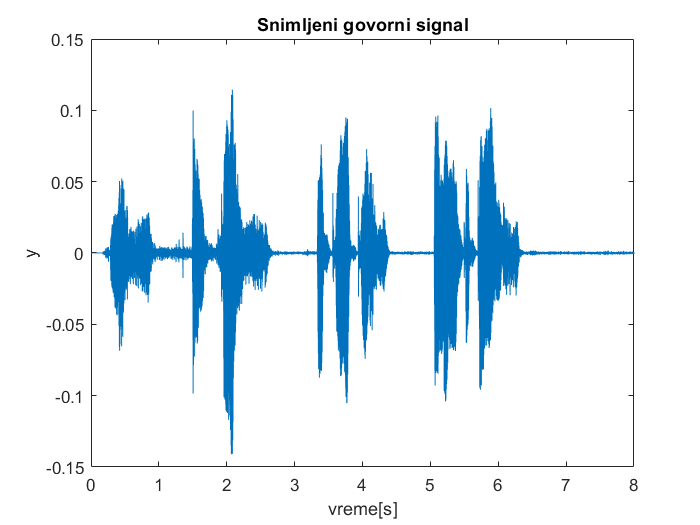

clear all;
close all;
clc;

fs=8000;% frekvencija odabiranja
trajanje_sek=8; % trajanje snimanja
N=trajanje_sek*fs; % broj odbiraka snimljenog signala
T=1/fs; % perioda odabiranja

[y, fs]=audioread('recisasamoglasnicima.wav');
%%
figure(1)
plot(T:T:length(y)*T,y)
title('Snimljeni govorni signal')
xlabel('vreme[s]')
ylabel('y')

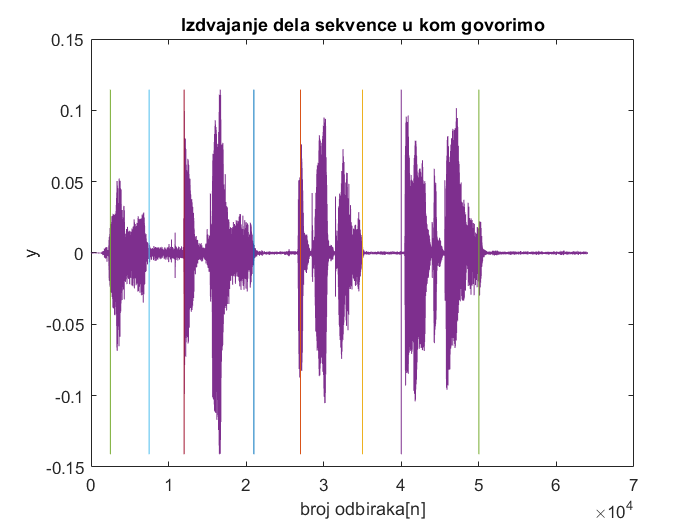

poceci = [2500 12000 27000 40000];
krajevi = [7500 21000 35000 50000];
estim = [];
figure(2)
n = length(y);
plot(1:n,y);
hold all
for i=1:length(poceci)
    [y, fs]=audioread('recisasamoglasnicima.wav');
    poc = poceci(i);
    kraj = krajevi(i);
    %n=length(y);
    plot([poc poc], [min(y) max(y)], [kraj, kraj], [min(y) max(y)]);
    
    yc=y(poc:kraj);
    
    N=kraj-poc+1;
    
    %% Filtriranje
    
    [B, A]=butter(6, [100 900]/(fs/2));
    ycf=filter(B,A, yc);
    
    
    %% Formiranje povorki impulsa
    
    m1=zeros(1, N);
    m2=zeros(1, N);
    m3=zeros(1, N);
    m4=zeros(1, N);
    m5=zeros(1, N);
    m6=zeros(1, N);
    m4pom=zeros(1, N); % vrednosti (intenziteti) minimuma
    maksp=[]; % pozicije (indeksi) maksimuma
    minp=[]; % pozicije (indeksi) minimuma
    
    % Formiranje m1 i m4
    
    % Povorka m1 se formira tako sto se na pozicijama maksimuma postavljaju
    % vrednosti koje se dobijaju kao maksimum od 0 i tekuceg maksimuma
    % Povorka m4 se formira tako sto se na pozicijama minimuma postavljaju
    % vrednosti koje se dobijaju kao maksimum od 0 i negativne vrednosti
    % tekuceg minimuma
    
    for i=2:N-1
        if ycf(i)>ycf(i-1) && ycf(i)>ycf(i+1)
            m1(i)=max(0, ycf(i));
            maksp=[maksp i];
        end
        
        if ycf(i)<ycf(i-1) && ycf(i)<ycf(i+1)
            m4pom(i)=ycf(i);
            m4(i)=max(0, -ycf(i));
            minp=[minp i];
        end
    end
    
    % Formiranje m2 i m3
    
    % Povorka m2 se formira tako sto se na pozicijama maksimuma postavljaju
    % vrednosti koje se dobijaju kao maksimum od 0 i razlike tekuceg maksimuma
    % i prethodnog minimuma
    % Povorka m3 se formira tako sto se na pozicijama maksimuma postavljaju
    % vrednosti koje se dobijaju kao maksimum od 0 i razlike tekuceg maksimuma
    % i prethodnog maksimuma
    
    tmp1=0; % vrednost prethodnog minimuma
    tmp2=0; % vrednost prethodnog maksimuma
    
    for i=maksp
        m2(i)=max(0, m1(i)-tmp1);
        m3(i)=max(0, m1(i)-tmp2);
        
        % Priprema za narednu iteraciju
        
        tmp2=m1(i);
        % Nalazenje indeksa i vrednosti prethodog minimuma za sledecu iteraciju
        % kao sledeci minimum nakon trenutne pozicije maksimuma
        ind=minp(find(minp>i, 1, 'first'));
        tmp1=m4pom(ind);
    end
    
    % Formiranje m5 i m6
    
    % Povorka m5 se formira tako sto se na pozicijama minimuma postavljaju
    % vrednosti koje se dobijaju kao maksimum od 0 i negativne vrednosti
    % razlike tekuceg minimuma i prethodnog maksimuma
    % Povorka m6 se formira tako sto se na pozicijama minimuma postavljaju
    % vrednosti koje se dobijaju kao maksimum od 0 i negativne vrednosti
    % razlike tekuceg minimuma i prethodnog minimuma
    
    tmp1=0; % pozicija prethodnog maksimuma
    tmp2=0; % pozicija prethodnog minimuma
    
    for i=minp
        m5(i)=max(0, -(m4pom(i)-tmp1));
        m6(i)=max(0, -(m4pom(i)-tmp2));
        
        % Priprema za narednu iteraciju
        tmp2=m4pom(i);
        ind=maksp(find(maksp>i, 1, 'first'));
        tmp1=m1(ind);
    end
    
    %figure(3);
    %subplot(7,1,1); plot(ycf(1:600));
    %subplot(7,1,2); plot(m1(1:600));
    %subplot(7,1,3); plot(m2(1:600));
    %subplot(7,1,4); plot(m3(1:600));
    %subplot(7,1,5); plot(m4(1:600));
    %subplot(7,1,6); plot(m5(1:600));
    %subplot(7,1,7); plot(m6(1:600));
    
    %% Procena pitch periode
    
    m1=m1(500:end);
    m2=m2(500:end);
    m3=m3(500:end);
    m4=m4(500:end);
    m5=m5(500:end);
    m6=m6(500:end);
    N=length(m1);
    
    % Parametri za estimatore
    win=fs*15e-3; % Prozor duzine 15ms u odbircima
    NN=floor(N/win); % Broj prozora bez preklapanja
    lambda=120/fs; % 120 s^-1 u odbircima
    tau=fs*3e-3; % blanking time, 3ms u odbircima
    
    % Pocetne vrednosti estimatora se postavljaju na nule
    % Radimo bez preklapanja prozora
    E1=zeros(1, NN-1);
    E2=zeros(1, NN-1);
    E3=zeros(1, NN-1);
    E4=zeros(1, NN-1);
    E5=zeros(1, NN-1);
    E6=zeros(1, NN-1);
    E=zeros(1, NN-1); %kombinovana estimacija, median
    
    for i=2:NN-1
        
        % Estimatori
        
        % Prvi estimator
        y=m1((i-1)*win+1:(i-1)*win+win); % sa +win je omoguceno da nema preklapanja (moze da se radi i sa preklapanjem, ali je ovo jednostavnije)
        E1(i)=Estimator(y, lambda, tau, win);
        
        % Drugi estimator
        y=m2((i-1)*win+1:(i-1)*win+win);
        E2(i)=Estimator(y, lambda, tau, win);
        
        % Treci estimator
        y=m3((i-1)*win+1:(i-1)*win+win);
        E3(i)=Estimator(y, lambda, tau, win);
        
        % Cetvrti estimator
        y=m4((i-1)*win+1:(i-1)*win+win);
        E4(i)=Estimator(y, lambda, tau, win);
        
        % Peti estimator
        y=m5((i-1)*win+1:(i-1)*win+win);
        E5(i)=Estimator(y, lambda, tau, win);
        
        % Sesti estimator
        y=m6((i-1)*win+1:(i-1)*win+win);
        E6(i)=Estimator(y, lambda, tau, win);
        
        E(i)=median([E1(i) E2(i) E3(i) E4(i) E5(i) E6(i) E(i-1)]);
        
        % Filtriranje
        if i>2
            E(i)=0.95*E(i-1)+0.05*median([E1(i) E2(i) E3(i) E4(i) E5(i) E6(i) E(i-1)]);
        else
            E(i)=median([E1(i) E2(i) E3(i) E4(i) E5(i) E6(i) E(i-1)]);
        end
    end
    
    %figure;
    %plot(1./(E/fs));
    estim = [estim median(1./(E/fs))];
end
title('Izdvajanje dela sekvence u kom govorimo')
xlabel('broj odbiraka[n]')
ylabel('y')
hold off


% konacna estimacija moze da se dobije na primer kao:
F0 = mean(estim)

F0 = 193.3046

#### ***DRUGI METOD:***

Druga metoda korišćena u ovom zadatku jeste metoda zasnovana na proceni autokorelacione funkcije. Autokorelaciona funkcija se računa preko formule


$$R_{x}(k) = E\{x(n)x(n+k)\}$$


a usled nepoznavanja gustine verovatnoće odbiraka procesa, može se estimirati kao


$$\hat{R}_{x}(k) = \lim_{N->\infty } \frac{1}{2N+1}\sum_{n=-N}^{N}x(n)x(n+k)$$


odnosno u realnim procenama:


$$\[ \hat{R}_{x}(k) = \frac{1}{2N+1}\sum_{n=-N}^{N}x(n)x(n+k) \]$$


Ako je signal x(n) periodičan sa periodom ponavljanja P, autokorelaciona fja bi morala biti periodična sa istom periodom P, a na grafiku Rx će biti izražen pik na vrednosti P. Pošto kod govornog signala postoje različite prostoperiodične komponente, u Rx će biti više izraženih pikova.

U postupku procene Rx koriste se prozorske funkcije koje imaju za cilj da procene ovu funkciju samo na jednom određenom segmentu signala. Tada se za Rx koristi sledeća formula:


$$\hat{R}_x^m(k) = \frac{1}{2N+1}\sum_{n=-N}^{N}x(n)w(m-n)x(n+k)w(m-n-k)$$


Iako su uočljivi pikovi u Rx, nije jasno koji od tih pikova potiče od osnovnog formanta. Zbog toga se često koriste tehnike klipovanja. One odrazumevaju da se na odbirke akustičnog talasa primene određene nelinearne funkcije. Za parametar Cl se obično preporučuje oko 30 

procenata od maksimalne vrednosti signala. Rx nakon klipovanja ima mnogo izraženiji pik i njegova pozicija se nalazi na poziciji pitch-periode. 

#### ***REZULTATI:***

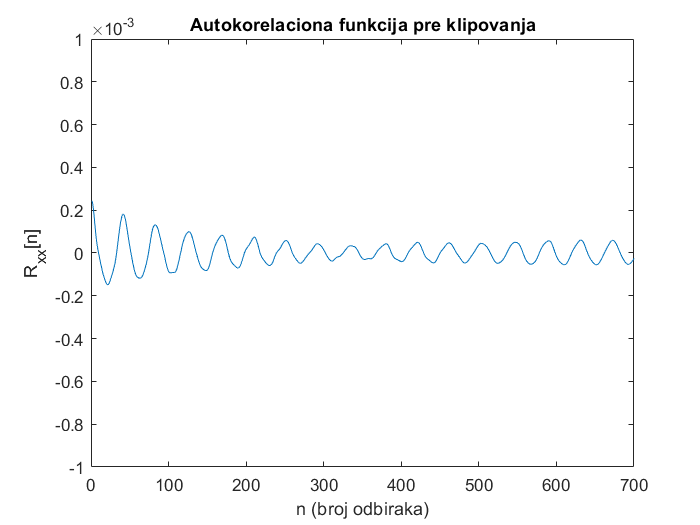

clear all;
close all;
clc;

%% Snimanje sekvence

% x=audiorecorder(fs,16,1);
% disp('Snimanje pocinje')
% recordblocking(x,trajanje)
% disp('Snimanje zavrseno')
% Snimljena je govorna sekvenca u trajanju od 6s koja sadrzi 6 reci
% onomatopeja, psihologija i samoglasnik

%% Reprodukcija zvuka

% y=getaudiodata(x);
% sound(y,fs);
% audiowrite('sekvenca_E.wav',y,fs);
[y, fs]=audioread('recisasamoglasnicima.wav');
poceci = [2500 12000 27000 40000];
krajevi = [7500 21000 35000 50000];
poc = poceci(1);
kraj = krajevi(1);
estim = [];
yc=y(poc:kraj);
%trajanje_sek = 8;
%N = fs*trajanje_sek;
N = kraj-poc+1;
T =1/fs;
% figure(1)
% plot(T:T:length(y)*T,y)
% title('Snimljeni govorni signal')
% xlabel('vreme[s]')
% ylabel('y')

%% Filtriranje

[B, A]=butter(6, [100 900]/(fs/2));
y_f=filter(B,A,y);

% Procena pitch periode pomocu autokorelacione funkcije

Rxx=AKF(y_f); % autokorelaciona funkcija bez klipovanja

figure
t=T:T:length(y_f)*T;
plot(t*fs, Rxx);
axis([0 700 -0.001 0.001 ])
title('Autokorelaciona funkcija pre klipovanja')
xlabel('n (broj odbiraka)')
ylabel('R_{xx}[n]')

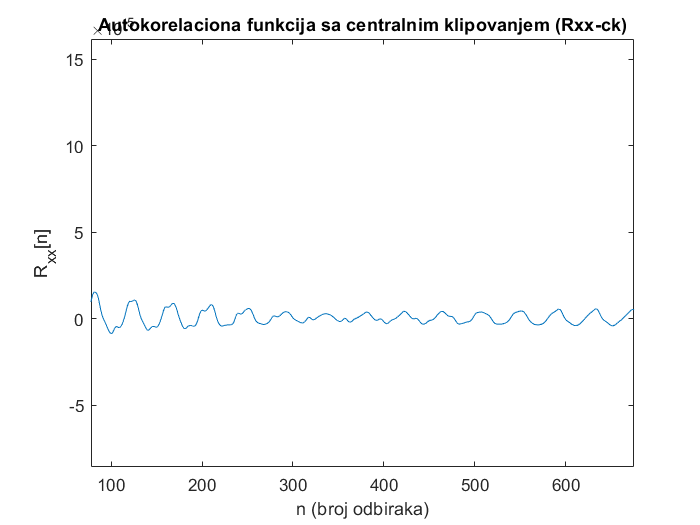


%% Centralno klipovanje

% y_centklip=0, za yf izmedju -cl i cl
% y_centklip=yf-cl, za yf>cl
% y_centklip=-yf+cl, za yf<cl
cl = 0.3*max(y_f); %cl moze biti u opsegu (30-60)%max(y)
y_ck=Centralno_klipovanje(y_f,cl);
Rxx_ck=AKF(y_ck); % autokorelaciona funkcija nakon centralnog klipovanja

figure
t=T:T:length(y_ck)*T;
plot(t*fs, Rxx_ck);
axis([0 700 -0.0001 0.0002 ])
title('Autokorelaciona funkcija sa centralnim klipovanjem (Rxx-ck)')
xlabel('n (broj odbiraka)')
ylabel('R_{xx}[n]')

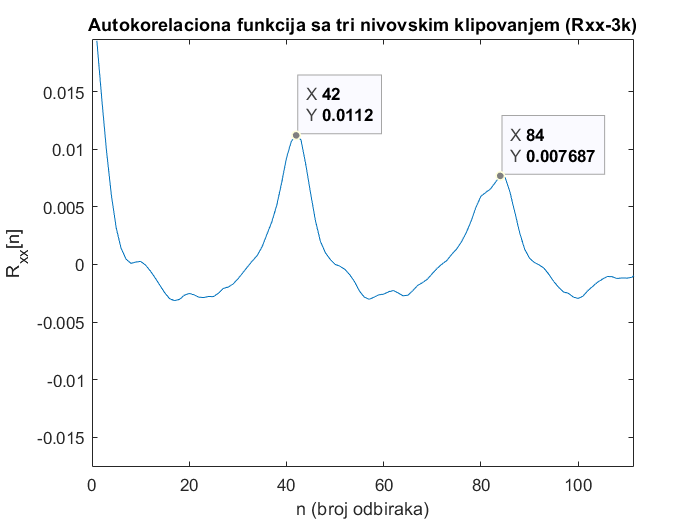


%% Tri nivovsko klipovanje

% y_3k=0, za yf izmedju -cl i cl
% y_3k=1, za yf>cl
% y_3k=-1, za yf<cl
cl = 0.5*max(y_f); %cl moze biti u opsegu (30-60)%max(y)
y_3k=Tri_nivovsko_klipovanje(y_f, cl);
Rxx_3k=AKF(y_3k);

figure
t=T:T:length(y_3k)*T;
plot(t*fs, Rxx_3k);
axis([0 700 -0.05 0.1 ])
title('Autokorelaciona funkcija sa tri nivovskim klipovanjem (Rxx-3k)')
xlabel('n (broj odbiraka)')
ylabel('R_{xx}[n]')

% DOBIJA SE PROCENA 42 odb prema 64000, x prema 8000ms, odatle je T=5.25ms,
% odnosno F0 = 190.45 Hz

## Drugi zadatak:

#### 1. Korišćenjem komercijalnog mikrofona u programskom okruženju MATLAB, snimiti govornu sekvencu u dužini od 20-ak sekundi. Sekvencu snimiti sa frekvencijom odabiranja 8 kHz u šesnaestobitnoj (default) rezoluciji.

#### 2. Isprojektovati 𝜇 = 100 i 𝜇 = 500 kompanding kvantizator sa 4, 8 i 12 bita i za njih odrediti zavisnost odnosa signal-šum za različite vrednosti odnosa (𝑋𝑚𝑎𝑥/𝜎𝑥 ). Ovaj odnos menjati promenom varijanse korisnog signala, prostim skaliranjem početne snimljene sekvence. Prikazati rezultate grafički.

### ***TEORIJSKI OSVRT:***

U digitalizaciji govornog signala od značaja su kvantizacija po vremenu (odabiranje), i po amplitudi (kvantizatori o kojima će ovde biti reči). Zadatak kvantizatora jeste da ulazni diskretni signal x(n) koji može uzeti bilo koju vrednost od -Xmax do Xmax, preslika u neki signal x1(n) koji uzima vrednosti iz diskretnog skupa sa konačnim brojem elemenata. Ovo omogućava kodiranje signala koji se dalje šalje u komunikacioni kanal. Ono o čemu je potrebno voditi računa i u ovom delu digitalizacije govornog isgnala jeste da gubitak informacija koji  nastaje kvantizacijom bude minimalan. 

     4



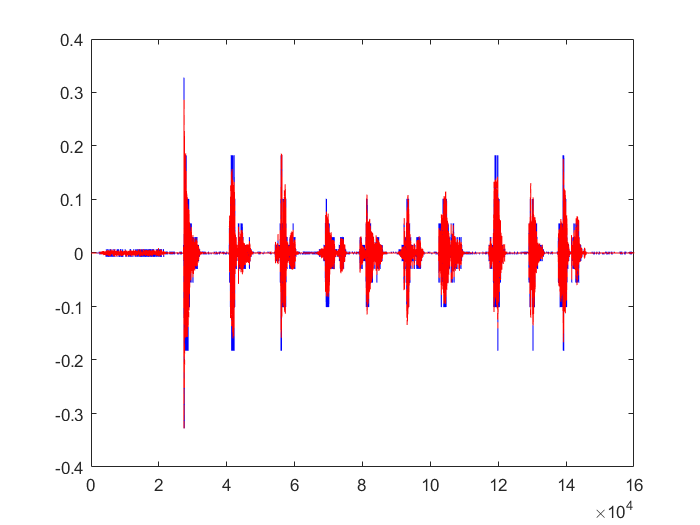

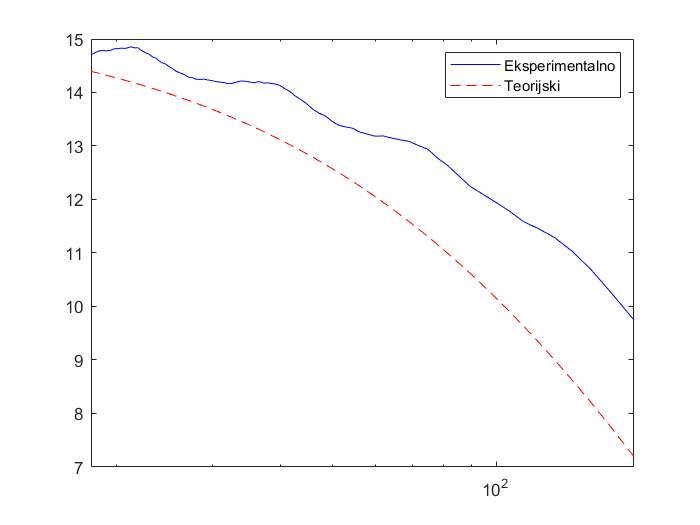

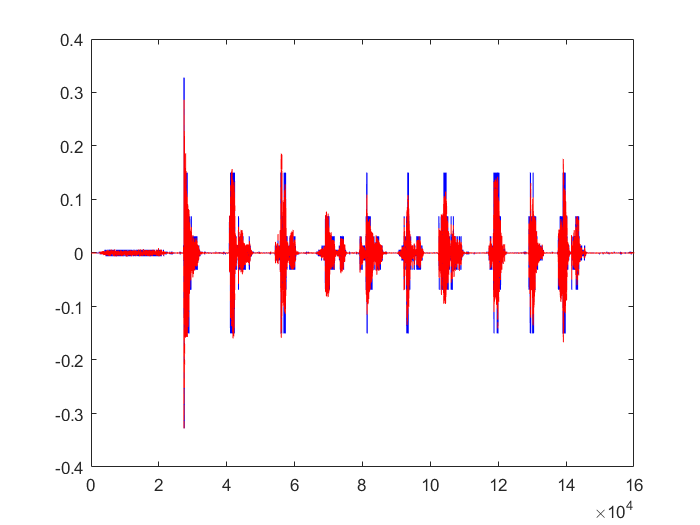

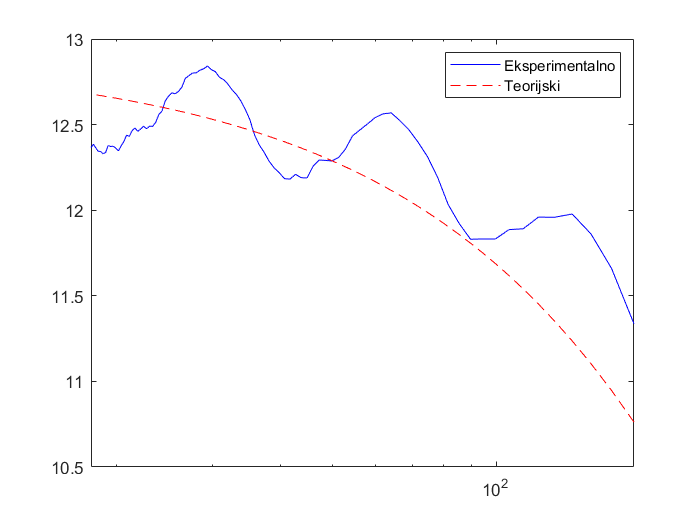

     8



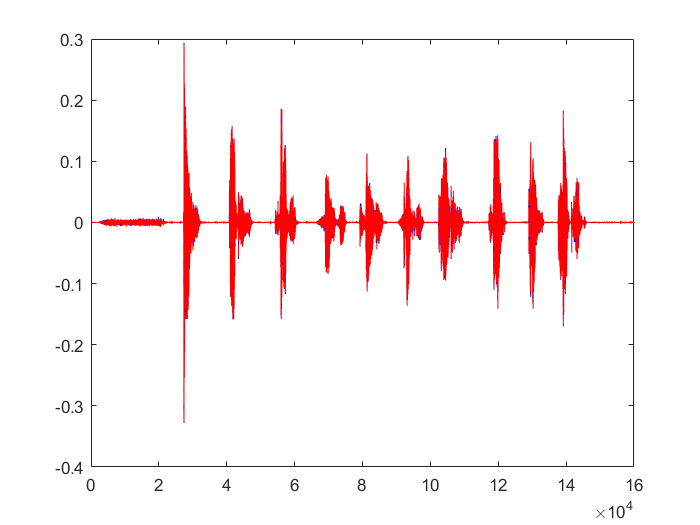

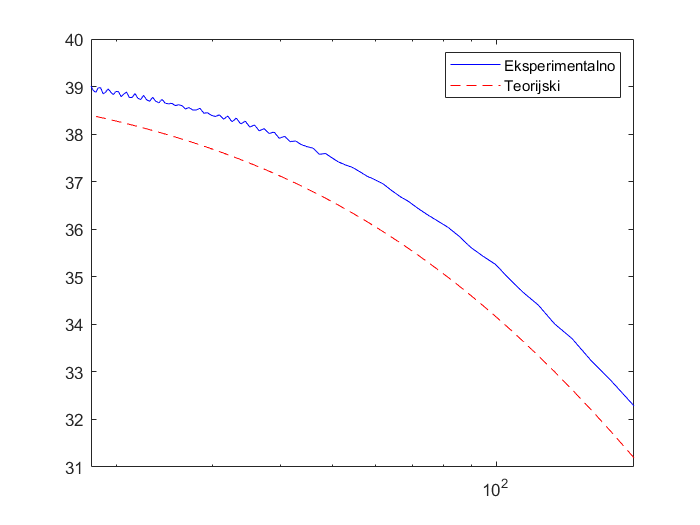

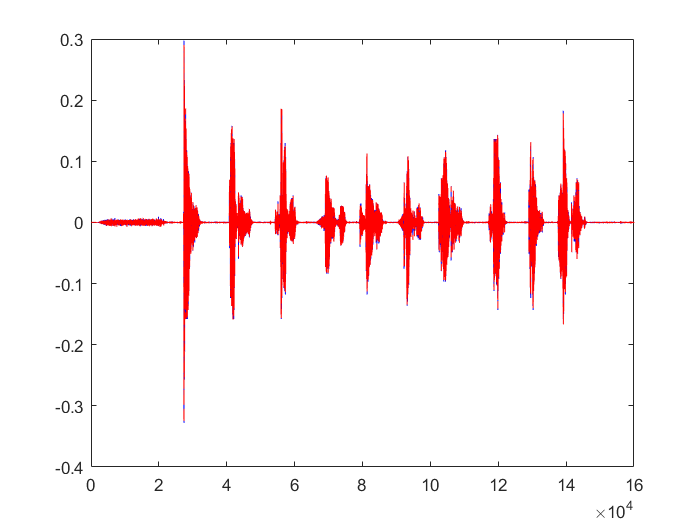

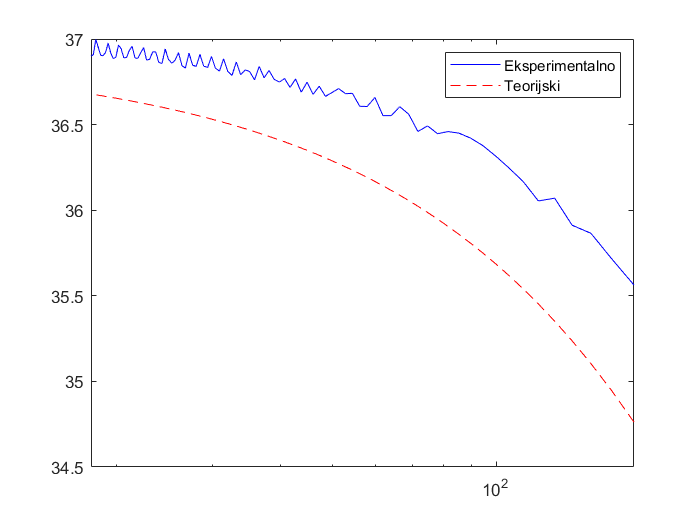

    12



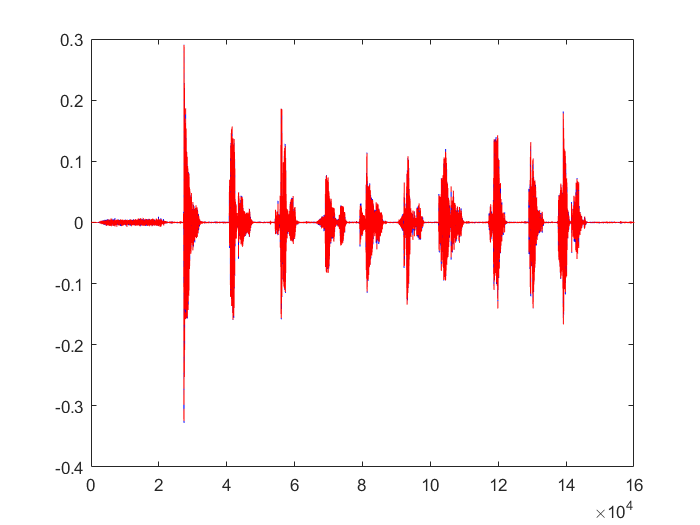

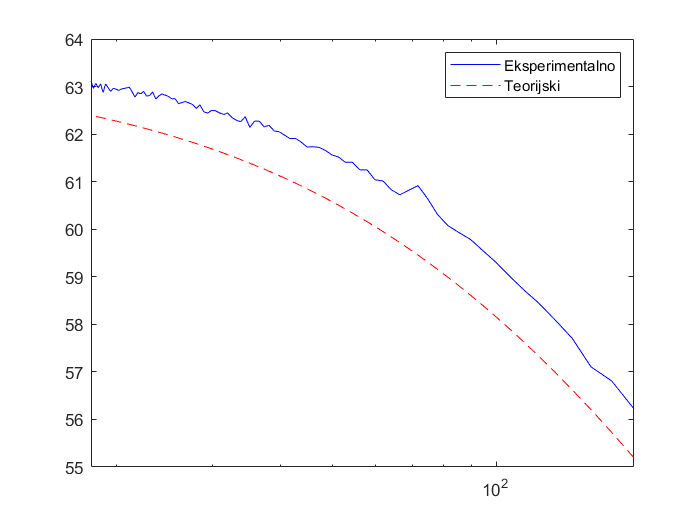

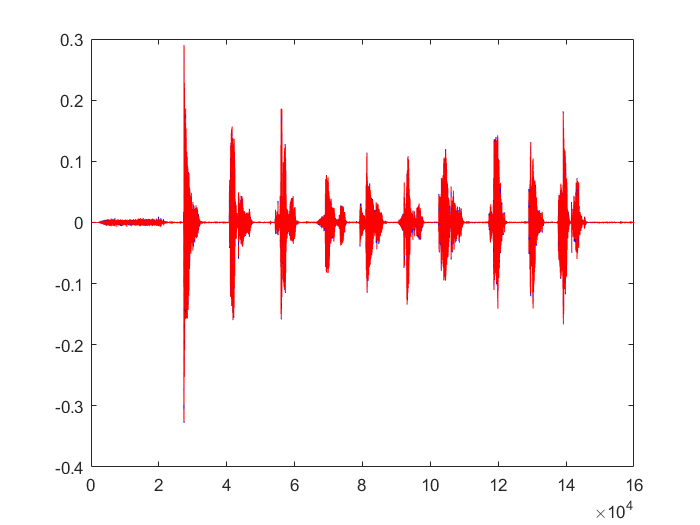

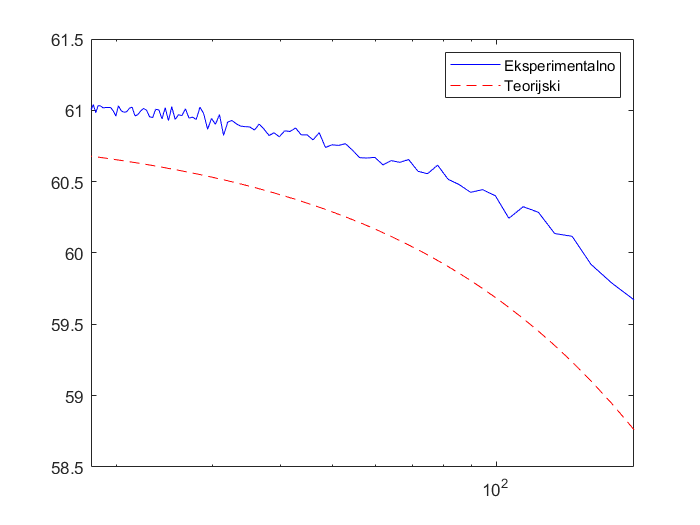

clear

[x,Fs]=audioread('sekvenca.wav');
Xmax = max(abs(x));
N = length(x);
b = 8;
M = 2^b;

d = 2*Xmax/(2^b);
Xmax = max(abs(x));
br_bit = [4,8,12];

for b = br_bit
    disp(b)
    for mi=[100,500]
        aten = 0.1:0.01:1; %atenuacija/utisavanje
        M = 2^b; %broj kvantizacionih nivoa
        d = 2*Xmax/M; %korak kvantizacije
        SNR1 = [];
        xvar1 = [];
        for i=1:length(aten)
            x1 = aten(i)*x;
            xvar1 = [xvar1 var(x1)];
            x_comp = Xmax*log10(1+mi*abs(x1)/Xmax)/(log10(1+mi)).*(sign(x1));
            xq_mi = round(x_comp/d)*d; %kvantizovan signal
            %xq_mi
            x_mi_decomp =1/mi*sign(xq_mi).*((1+mi).^(abs(xq_mi)/Xmax)-1)*Xmax;
            SNR1 = [SNR1 10*log10(var(x1)/var(x1-x_mi_decomp))];
        end
        figure
        plot(1:N,x_mi_decomp,'b');
        hold on;
        plot(1:N,x,'r--');
        hold off
        figure
        semilogx(Xmax./(sqrt(xvar1)),SNR1,'b');
        %plot(Xmax./(sqrt(xvar)),SNR,'b');
        hold on;
        %semilogx(Xmax./(sqrt(xvar)),4.77+6*b-20*log10(Xmax./sqrt(xvar)),'r--');
        semilogx(Xmax./(sqrt(xvar1)),4.77+6*b-20*log10(log(1+mi))-10*log10(1+(Xmax./mi)^2./xvar1+sqrt(2)*Xmax./mi./sqrt(xvar1)),'r--');
        legend('Eksperimentalno','Teorijski')
        %fprintf('SNR = %f\n', 10*log10(var(x)/var(x-x_mi_decomp)));
    end
    hold off
end

#### 3. Isprojektovati Delta kvantizator za sekvencu iz tačke 1. Adekvatno podesiti parametar Δ tako da se dobije što bolji kvalitet kvantizacije. Uporediti oblike originalnog i kvantizovanog signala. Šta se dešava kada je korak kvantizacije Δ previše mali ili previše veliki? Da li se histogram priraštaja može koristiti za određivanje adekvatnog parametra Δ? Pratiti kvalitet zvuka i promene u amplitudi za svaki slučaj

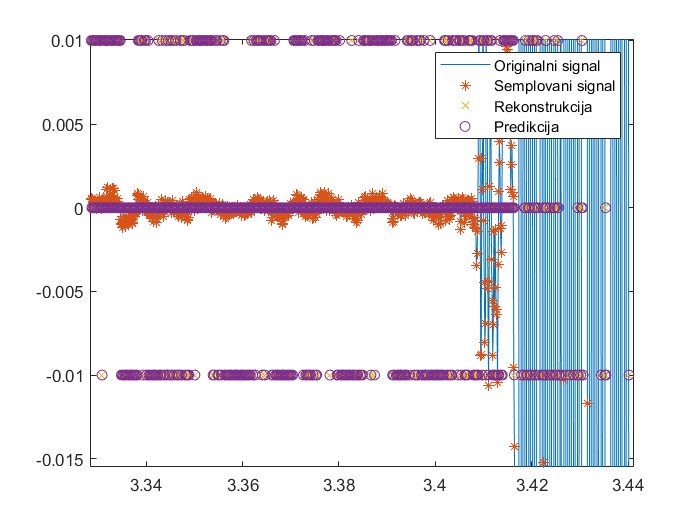

clear

[x,Fs]=audioread('sekvenca.wav');
L = length(x);
t = 0:1/Fs:(length(x)-1)/Fs;

%fs = 30;
%t = 0:1/fs:1;
%L = length(t);
%f = 2;
%x = (sin(2*pi*f*t) + 1.0)/2*255;
%x = round(x);

%parametri
%maxdxdt = 0.3533
%T = 1/fs = 1.25e-04;
%Delta>1/fs*0.3533 = 4.4163e-05;
Q = 0.01;
xmean = mean(x);

%pocetni uslovi
d = zeros(1,L);
d(1) = x(1);
c = zeros(1,L);
dd = zeros(1,L);
dd(1) = Q;
xx = zeros(1,L);
xx(1) = xmean + dd(1);

%delta modulacija
for i=2:L
    d(i) = x(i)-xx(i-1);
    if d(i)>0
        c(i) = 0;
        dd(i) = Q;
    else
        c(i) = 1;
        dd(i) = -Q;
    end
    xx(i) = xx(i-1) + dd(i);
end

figure
plot(t,x,t,x,'*',t,xx,'x',t(2:L),xx(1:(L-1)),'o');
legend('Originalni signal','Semplovani signal', 'Rekonstrukcija','Predikcija');


%plot(0:1/Fs:(length(x)-1)/Fs, x);
%hold on;
%plot(0:1/Fs:(length(x)-1)/Fs,xx,'*')
%hold off


